Maximum similarity: 186.4059 at lag 71


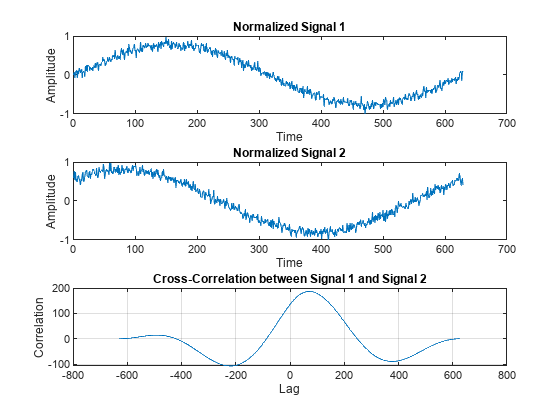

% Example signals (sine waves with noise and different phases)
t = 0:0.01:2*pi;
signal1 = sin(t) + 0.1*randn(size(t));
signal2 = sin(t + pi/4) + 0.1*randn(size(t));

% Call the function to compare signals
similarity = compareSignals(signal1, signal2);

Maximum similarity: 225.7904 at lag 72


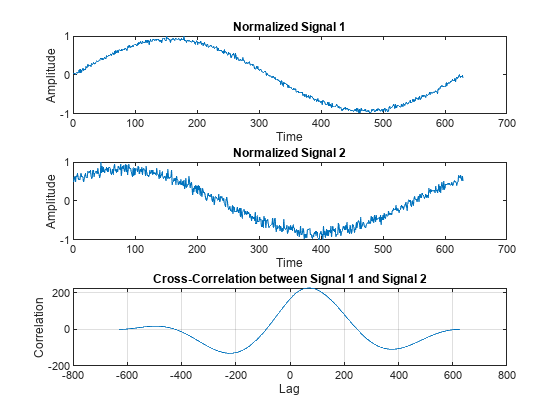

% Example signals (sine waves with noise and different phases)
t = 0:0.01:2*pi;
signal1 = 3*sin(t) + 0.1*randn(size(t));
signal2 = sin(t + pi/4) + 0.1*randn(size(t));

% Call the function to compare signals
similarity = compareSignals(signal1, signal2);

function similarity = compareSignals(signal1, signal2)
    % Remove the mean (detrend)
    signal1_detrended = signal1 - mean(signal1);
    signal2_detrended = signal2 - mean(signal2);

    % Normalize the amplitude
    signal1_normalized = signal1_detrended / max(abs(signal1_detrended));
    signal2_normalized = signal2_detrended / max(abs(signal2_detrended));

    % Calculate cross-correlation
    [crossCorr, lags] = xcorr(signal1_normalized, signal2_normalized);

    % Find the maximum value of the cross-correlation
    [similarity, maxLagIndex] = max(crossCorr);
    lagAtMaxSimilarity = lags(maxLagIndex);

    % Display results
    fprintf('Maximum similarity: %.4f at lag %d\n', similarity, lagAtMaxSimilarity);

    % Plot the signals and cross-correlation for visualization
    figure;
    subplot(3, 1, 1);
    plot(signal1_normalized);
    title('Normalized Signal 1');
    xlabel('Time');
    ylabel('Amplitude');

    subplot(3, 1, 2);
    plot(signal2_normalized);
    title('Normalized Signal 2');
    xlabel('Time');
    ylabel('Amplitude');

    subplot(3, 1, 3);
    plot(lags, crossCorr);
    title('Cross-Correlation between Signal 1 and Signal 2');
    xlabel('Lag');
    ylabel('Correlation');
    grid on;
end
